# **线性分组码识别分析**

参考资料：张永光《信道编码识别分析》

本篇文章聚焦线性分组码的编码、解码、逆向分析。

只讨论系统码。

## 0. 组成

    线性分组码的大体分类可以总结如下：


$$\mathrm{线性分组码}\;\left\lbrace \begin{array}{c}
\mathrm{汉明码}\\
\mathrm{循环码}\left\lbrace \begin{array}{c}
\mathrm{BCH码}\left\lbrace \begin{array}{c}
\mathrm{RS码}\\
\mathrm{其他BCH码}
\end{array}\right.\\
\mathrm{其他循环码}
\end{array}\right.\\
\mathrm{其他线性分组码}
\end{array}\right.$$


## 1.  汉明码

### 1.1 构造原理

        汉明码是一种能够纠正一位错码且编码效率较高的线性分组码。

       一种（7,4）汉明码，码型$a_6 a_5 a_4 a_3 a_2 a_1 a_0$。其中$a_6 a_5 a_4 a_3$为信息位，$a_2 a_1 a_0$为监督位。监督关系为$a_2 =a_6 \oplus a_5 \oplus a_4 ;\;\;\;a_1 =a_6 \oplus a_5 \oplus a_3 ;\;\;\;\;a_0 =a_6 \oplus a_4 \oplus a_3 ;$ 

监督位的计算结果见《通信原理第六版》表11-4。

      由以上关系，可以确定生成矩阵G和监督矩阵H，如下代码。这里只讨论系统码，编码后，信息位不变，监督位附加在其后。还有一种G，编码后，信息位在后，相应的G中单位阵在后。此外，系统码的校验矩阵H对应唯一的生成矩阵G，而非系统码的校验矩阵对应多个生成矩阵，需要进一步分析排除。据资料在实际中也是系统码比较多。

n=7;k=4;r=3;%码长，信息位长，监督位长
P = [1 1 1 0; 1 1 0 1; 1 0 1 1]

P =      1     1     1     0
     1     1     0     1
     1     0     1     1


H = [P eye(r)]  %监督矩阵

H =      1     1     1     0     1     0     0
     1     1     0     1     0     1     0
     1     0     1     1     0     0     1


Q = P'  

Q =      1     1     1
     1     1     0
     1     0     1
     0     1     1


G = [eye(k) Q]  %生成矩阵

G =      1     0     0     0     1     1     1
     0     1     0     0     1     1     0
     0     0     1     0     1     0     1
     0     0     0     1     0     1     1


##     1.2 编码

汉明码编码就是信息字与生成矩阵相乘，就得到了一个编码后的码字。如下代码生成了1000个码子。

slen = 1000; %比特流长度
msg = randi([0,1], slen, k);
scodewords = mod(msg*G,2);
sbits = reshape(scodewords',1,slen*n);

下面是利用matlab自带的hammgen函数进行汉明码生成。但是生成矩阵的中的单位阵在后面，监督矩阵的单位阵在前面。

%matlab自带得到hammgen函数,可以自动生成校验矩阵和生成矩阵。但是生成矩阵的中的单位阵在后面，监督矩阵的单位阵在前面。
%[H,G,N,K] = hammgen(3);
%在利用高斯直接解法识别的时候，化成行最简矩阵的时候要把单位阵移到前面，然后的生成完了之后再移回去
%另外：利用hammgen的生成矩阵生成的码字中，信息位在后。对应生成矩阵中单位阵在后。

##     1.3 经过信道接收码字

经过信道后，会有比特错误，接收到的码字起点可能不是码字的起点，这些都要考虑到。

errorrate = 1e-2;%误码率
rbits = mod(sbits + randerr(1,length(sbits),errorrate*length(sbits)),2);%加上误码
rbits_startunknown = rbits(randi([1 n]):end);%随机起始位置

##     1.4 译码

    通信协作方拿到比特流后，当然是知道的n，k，r，G，H这些参数的。这样全部的码组就可以知道了，码字的起始位置通过比对自然也是可知的。比如依次从第1比特开始取出10码字，看合法码字是否占多数，就可以确定码子起始位置。当然，协作方也可以通过发送全1或者全0来标识发送起始，还可以通过某种的约定或者同步电路（猜测）来确定码字起始位置。

    不管怎样，现在已经拿到了码字的起始位置。就可以重组码字，然后依次判断码字是否有错，从而进行纠错了。

rcodewords = reshape(rbits,n,slen);%这里直接用起始位置为0的比特流；因为协作方可以轻易确定起始位置
rcodewords = rcodewords';%每行是一个码字

    假设接收到一个码字B，很显然的，B = A + E，其中A为发送码字，E为错误图样。

        
$$B*H\prime =A*H\prime +E*H\prime =E*H\prime$$


    上式也证明了，S只与E有关，与A无关。这就说明S和错码之间存在着确定的线性变换关系。针对这里的（7,4）汉明码而言，S是一个1*r = 1*3的向量，而码长n=7, 则S正好能够指示7个错误的位置加上一个无错比特全零的情况。仅有一位错的时候，E里面只有一个1位于第L比特，那么S就是H的第L列, 在B的第L比特上模2加1即可纠一位错。两位或者两位以上的错误，已经超出了汉明码额纠错能力，无法正确纠错。

%分组码的译码，以码字为单位进行
HT = H';
for i = 1:length(rcodewords)
    S = mod(rcodewords(i,:)*(H'),2);%校正子，纠一位错
    if any(S)  %有错,2^r次
        %查看S是H'的第几行
        for j = 1:n
            if ~any(mod(HT(j,:)+S,2))%找到了
                break;%循环停下来时候的j就是错误位置
            end
        end
        rcodewords(i,j) = mod(rcodewords(i,j)+1,2);
    end
    %译码
end
rinfowords = rcodewords(:,1:k);
[errnum,errratio] = biterr(scodewords,rcodewords)%计算误比特数和误码率

errnum = 0

errratio = 0

##     1.5 逆向分析

###     1.5.1 解方程法

        本节主要是根据《信道编码及其识别分析 2.2.1节 高斯法解方程》进行学习。

        解方程法的思想：

        汉明码中，任意两个码字的和肯定是一个码字，证明如下。$\mathrm{C1}*H^T =0;\mathrm{C2}*H^T =0;\;\Rightarrow \left(\mathrm{C1}+\mathrm{C2}\right)*H^T =0;\;$

- 所有的码字中，线性不相关的肯定是k个。G也是由k个线性不相关的码字组成的。

- 如果线性不相关的码字个数大于k,那么生成矩阵将不能生成全部的码字；

- 如果线性不相关的码字个数小于k,那么生成矩阵也不能生成全部$2^k$个码字了。

        所以，在所有的接收比特流中，可以找到k个线性不相关的码字,${B=\;\left(\mathrm{C1}\;\mathrm{C2}\;\mathrm{C3}\;\mathrm{C4}\right)}^T$. 那么$B*H^T =0$。如果把H求出来，那么就完成了识别。

        B经过初等行变换之后，依然满足上式。此时，把B写为$\left\lbrack I_k \;Q_{k*r} \right\rbrack$的形式。令$H^T =\left\lbrack \begin{array}{c}
Q_{k*r} \\
I_r 
\end{array}\right\rbrack$,此时，模2加基础上，$B*H^T =Q_{k*r} +Q_{k*r} =0$，满足要找的H。

        该方法基于如下假设：n，k已知；码字起始比特已知；

p3rcodewords = scodewords;%第三方收到的码字,n,k,码字起始比特已经知道,没有误码。
simrowsformat = transSimplestRowsGF2(p3rcodewords(1:100,:))%拿出来100行化简为行最简

simrowsformat =      1     0     0     0     1     1     1
     0     1     0     0     1     1     0
     0     0     1     0     1     0     1
     0     0     0     1     0     1     1
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0


G1 = simrowsformat(1:k,:);% 生成矩阵G就是行最简形的前k行
Q1 = G1(:,k+1:end);
P1 = Q1';
H1 = [P1 eye(r)]

H1 =      1     1     1     0     1     0     0
     1     1     0     1     0     1     0
     1     0     1     1     0     0     1


    至此，G和H矩阵就顺利的分析出来了。

    最后还得指出，这种方法的应用条件非常的苛刻，

- n已知

- k已知

- r已知

- 码字起始比特

- 数据无误码

    上述条件都符合，才能得到有效的G.

    下面讨论一下，如果不知道码字起始，利用高斯直解法能否得到结果。条件在无误码，nkr参数已知。

%假设一个起始位置
startbit = 2;%码流首比特在码字中的位置

rbitsNoNoise = sbits(startbit:end);
rcodewords = reshape(rbitsNoNoise(1:floor(length(rbitsNoNoise)./n)*n),n,floor(length(rbitsNoNoise)./n));
rcodewords = rcodewords';
simrowsformat = transSimplestRowsGF2V2(rcodewords(1:100,:))%拿出来100行化简为行最简

simrowsformat =      1     0     0     0     0     1     0
     0     1     0     0     1     0     0
     0     0     1     0     1     1     0
     0     0     0     1     1     1     0
     0     0     0     0     0     0     1
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0


结果表明除了正确的码字起始位置，其他位置都不能得到正确的$G=\left\lbrack \begin{array}{cc}
I_k  & Q
\end{array}\right\rbrack$的形式。这也就给了一个寻找码字起始比特的思路。当然， 应用这种方法的条件非常的苛刻，而且一般需要尝试n次。

###     1.5.2 码重分析法

    利用码重分析法主要来分析码长。

    原理：若估计码长不为真实码长，则分组内码字之间不存在约束关系，可以认为0 1 等概率出现。可假设此时数据的码重分布是等概率的模型，不同码重的码组出现的概率为1/(n+1)。其中码重分布距离公式 $D=\frac{n+1}{n}\sum_{i=0}^n {\left|P_i -\frac{1}{n+1}\right|}^2$，各码长对应的码重可以按照这个公式进行计算对比。

errorrate = 0.107;%误码率
startbit = 1;%码字起始比特
n1 = 8;%猜测的码长
%接收过程（噪声+起始比特随机），收到比特流
rbits = mod(sbits + randerr(1,length(sbits),floor(errorrate*length(sbits))),2);%加上误码
rbits = rbits(startbit:end);%随机起始位置

%根据猜测的码长构造接收码字
rcodewordsnum = floor(length(rbits)./n1);
rcodewords = reshape(rbits(1:rcodewordsnum*n1),n1,rcodewordsnum);
rcodewords = rcodewords';%每行一个码字

%计算每个码字的重量
wordweight = sum(rcodewords,2);
wordweightDistribute = zeros(1,n1+1);
for i = 0:n1
    wordweightDistribute(i+1) = sum(wordweight==i);
end
Prbi = wordweightDistribute./rcodewordsnum;
D = ((n1+1)./n1).*sum((Prbi-1/(n1+1)).*(Prbi-1/(n1+1)))

D = 0.0997

无误码条件下，起始码长确定，经过试验几种猜测码长和对应的的D值如下：

码长         3               4                 5               6              7                 8                 9

D值     0.0738       0.1010       0.1113      0.1184      0.3088        0.1228         0.1242

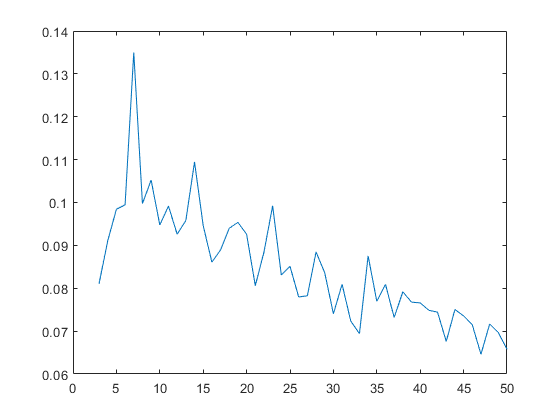

%直观的画图来看一下码长的效果
n1vector = 3:50;%猜测的码长
Dvector = zeros(1,length(n1vector));%存储D值
for i = 1:length(n1vector)
    Dvector(i) = calcD(rbits,n1vector(i));
end
plot(n1vector,Dvector);

    经过上面的验证，发现码重分析法对于噪声的不是太敏感，但是对于起始比特是敏感的。如果码字起始比特不对，则无法顺利分析出响应的码重。

###     1.5.3 Walsh-Hadamard法分析法

    利用Walsh-Hadamard法分析法来寻找校验矩阵H和生成矩阵G。

    该分析法要求已知码长n,k和起始比特。

    首先构造的接收码字。

errorrate = 0.107;%误码率
startbit = 1;%码字起始比特
n1 = 7;%猜测的码长
%接收过程（噪声+起始比特随机），收到比特流
rbits = mod(sbits + randerr(1,length(sbits),floor(errorrate*length(sbits))),2);%加上误码
rbits = rbits(startbit:end);%随机起始位置

%根据码长构造接收码字
rcodewordsnum = floor(length(rbits)./n1);
rcodewords = reshape(rbits(1:rcodewordsnum*n1),n1,rcodewordsnum);
rcodewords = rcodewords';%每行一个码字


将接收的码字转为10进制数，并统计每个数字出现的个数。

%将接收到的码字转换为10进制数
rcodewordsDEC = zeros(rcodewordsnum,1);
for i = 1:n1
    rcodewordsDEC = rcodewordsDEC + rcodewords(:,8-i).*(2^(i-1));
end
%构造向量,统计每个数字出现的个数
rcodewordsDECDistribution = zeros(1,2^n1);
for i = 0:2^n1-1
   rcodewordsDECDistribution(i+1) = sum(rcodewordsDEC==i);
end

与hadamand矩阵相乘

%与Hadamard矩阵相乘
x1 = rcodewordsDECDistribution*hadamard(2^n1);

找到大于置信度的位置

%找大于置信度的位置
t = 3;
tk = ceil(t*sqrt(rcodewordsnum));
loc1 = find(x1>=tk)-1

loc1 =      0    30    45    51    71    89   106   116


%去掉全0位置
loc = loc1(2:end);
%回到二进制构造序列
H21 = zeros(n1,length(loc));
for i = 1:length(loc)
    H21(:,i) = dec2bin(loc(i),7)-48;
end
H21

H21 =      0     0     0     1     1     1     1
     0     1     1     0     0     1     1
     1     0     1     0     1     0     1
     1     1     0     0     1     1     0
     1     1     0     1     0     0     1
     1     0     1     1     0     1     0
     0     1     1     1     1     0     0


H22 = H21';
H23 = transSimplestRowsGF2([H22(:,k+1:end) H22(:,1:k)]);
H24 = H23(1:r,:);
H2 = [H24(:,r+1:end) H24(:,1:r)]

H2 =      1     1     1     0     1     0     0
     1     1     0     1     0     1     0
     1     0     1     1     0     0     1


至此，Walsh-Hadamard法可以将校验矩阵H有效的估计出来，并且可以有一定的抗噪声能力。

H矩阵分析出来后，G矩阵也可以经过转换分析出来。

Walsh-Hadamard法分析完毕。

###     1.5.4 综合分析法

    利用综合分析法

    若已知码长n,未知起始比特.每行防止整数倍的n个比特，进行GF2上的初等行变换，是可以确定的码字起始位置的。

errorrate = 0.107;%误码率
startbit = 2;%码字起始比特
n1 = 35;%猜测的码长
%接收过程（噪声+起始比特随机），收到比特流
rbits = mod(sbits + randerr(1,length(sbits),floor(errorrate*length(sbits))),2);%加上误码
rbits = rbits(startbit:end);%随机起始位置

%根据码长构造接收码字
rcodewordsnum = floor(length(rbits)./n1);
rcodewords = reshape(rbits(1:rcodewordsnum*n1),n1,rcodewordsnum);
rcodewords = rcodewords';%每行一个码字

res = transSimplestRowsGF2V3(rcodewords)

res =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

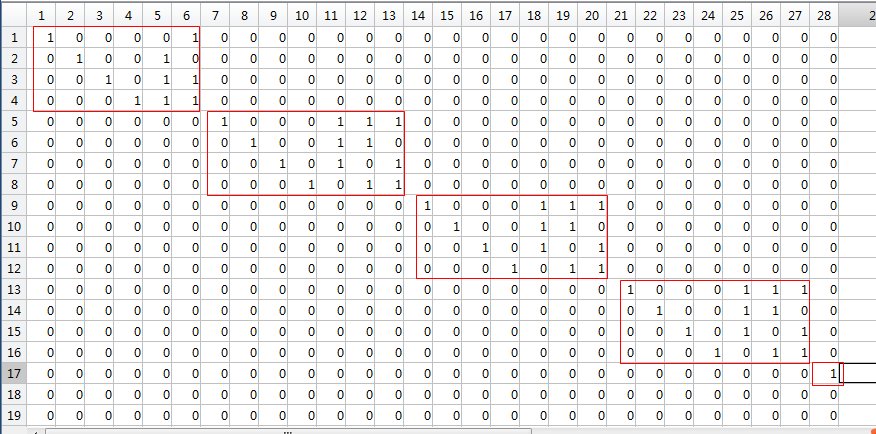

接下里考虑：码长n和起始点未知。

生成数据；

首先是码长。这时要估计一个码长n1,这个n1要比实际码长大。


errorrate = 0.001;%误码率
startbit = 2;%码字起始比特
n1 = 8;%猜测的码长
%求出2,3,……n1的最小公倍数nd
nd = 2;
for i = 2:n1
    nd = lcm(i,nd);
end

%接收过程（噪声+起始比特随机），收到比特流
rbits = mod(sbits + randerr(1,length(sbits),floor(errorrate*length(sbits))),2);%加上误码
rbits = rbits(startbit:end);%随机起始位置

%根据码长构造接收码字
rcodewordsnum = floor(length(rbits)./nd);
rcodewords = reshape(rbits(1:rcodewordsnum*nd),nd,rcodewordsnum);
rcodewords = rcodewords';%每行一个码字

res = transSimplestRowsGF2V3(rcodewords)

res =      1     0     0     0     0     1     0     0     0     1     0     1     1     1     0     0     0     1     1     1     1     1     0     0     0     0     1     1     0     0     0     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1
     0     1     0     0     1     0     0     1     1     1     0     0     0     0     1     1     1     0     0     0     1     0     0     1     1     0     0     0     0     1     0     1     0     1     1     0     0     1     1     0     0     0     0     0     1     0     1     1     0     1
     0     0     1     0     1     1     0     0     0     1     0     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     1     1     1     1     1     1     1     1     1     0     1     0     0     1     0     0     0     0     0     0     0     0     0     1
     0     0     0     1     1     1     0     0     0     1     0     1     1     1     0 

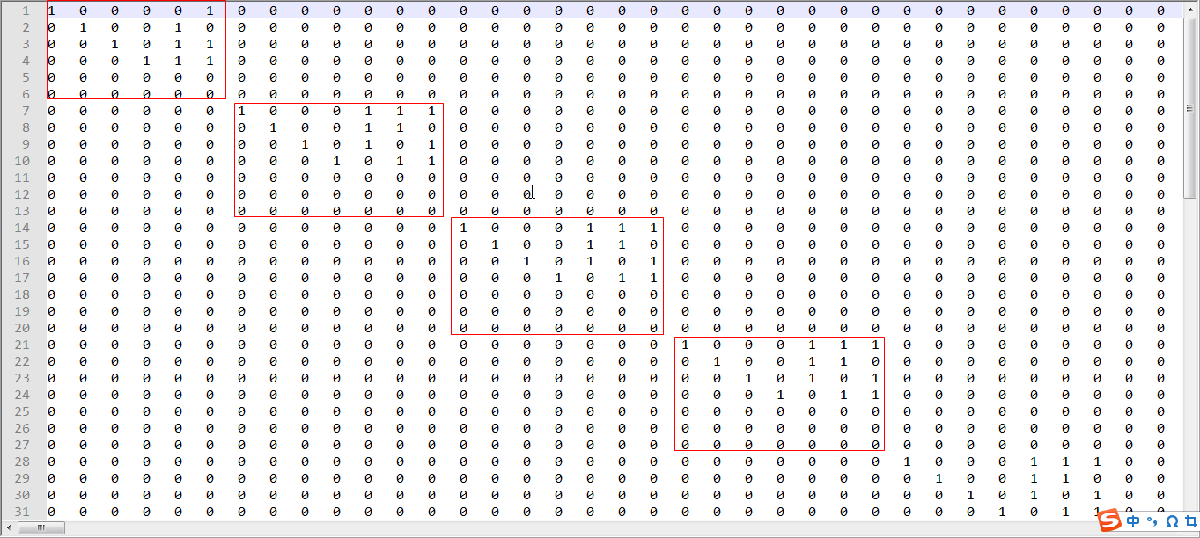

这种方法就是要求数据多。

这种方法可以抗一定的噪声，如果误码率不高，还是能够解出来合适的G的。

理论上只需要逐步增大猜测的码长，就可以得到符合要求的码长；但是随着的码长的增大，分析所需要的数据量也会急剧增大，导致实际意义不大。当然，如果事先有帧结构方面的先验知识或者通过分析得到真实码长，该方法还是有价值的。

###     1.5.5 线性矩阵分析法

分组码长度和分组码起始点的确定问题 。

errorrate = 0;%误码率
startbit = 3;%码字起始比特
n1 = 35;%猜测的码长
%接收过程（噪声+起始比特随机），收到比特流
rbits = mod(sbits + randerr(1,length(sbits),floor(errorrate*length(sbits))),2);%加上误码
rbits = rbits(startbit:end);%随机起始位置

该分析方法基于如下定理：对（n,k）线性分组码所构成的p*q矩阵（p>2*n,q<p），若q为n或者n的整数倍，则单位化后左上角单位阵的维数相等，且此时矩阵的秩不等于列数q。

p = 100;     % p值固定，p>2*n
q = 3:p;    % q是一个范围
qlist = [];
for i = 3:floor(p/2)     %循环列值
    %构造p*i的矩阵
    rcodewords = reshape(rbits(1:p*i),i,p);
    rcodewords = rcodewords';%每行一个码字
    %化成行最简形式
    ranki = rank(transSimplestRowsGF2V3(rcodewords));
    %这是合适的码长
    if(ranki ~= i)
        %留存这个i值。
        qlist = [qlist i];
    end    
end
qlist

qlist =      7    14    21    28    35    42    49


%求留存的值的最大公约数
n2 = qlist(1);
for j = 1:length(qlist)
    n2 = gcd(n2,qlist(j));
end
n2

n2 = 7

在我选的p,q参数里面，依然可以看出来绝大部分的留存值进行最大公因式的获取是由最大公因数7的。当q=p=50的时候，按照这种方法计算得到的矩阵的秩是 48，可能原因是当行列数据差别不大的时候，更容易的获得非满秩的矩阵把。故实际使用的时候，要求p值足够大，并且的p值也尽量大于的q值许多。

确定分组码分组的起点基于如下定理：对(n，k)线性分组码所构成的pxq矩阵(p>2n，q为n倍数)而言，当分组码起点与矩阵每行起点重合时，其秩最小(相应解空间维数最大)。

rankforstarts = zeros(1,n2);
%遍历起点求秩
for i = 1:n2
    rcodewords = reshape(rbits(i:p*n2+i-1),n2,p);
    rcodewords = rcodewords';%每行一个码字
    %化成行最简形式
    rankforstarts(i) = rank(transSimplestRowsGF2V3(rcodewords));
end
rankforstarts

rankforstarts =      6     7     7     6     5     4     5


%寻找最小的秩的位置
minranklocation = find(rankforstarts==min(rankforstarts))

minranklocation = 6

%正确的码字起点应该是(n2+2-startbit)
correctstart = (n2+2-startbit)-n2*floor((n2+2-startbit)/(n2+1))

correctstart = 6

有了码长和码字起始位置，就可以按照高斯消元法，进行行变换，化为行最简形，得到G和H，即可分析完毕。

接下来考虑分组码的另一个关键参数，即分组码的生成多项式g(x)。 

该部分讨论基于书上给出的如下定理：对(n,k)线性分组码生成矩阵G，其第k行的第k列到第n列即为生成多项式向量。

分组码中次数最低的多项式称为生成多项式，显然G中第k行的第k列到第n列即为生成多项式向量。

G(k,k:n)

ans =      1     0     1     1


    套用的书上的原话作为结尾：线性矩阵分析法通过线性变换在确定分组码的分组长度和分组起始点后，通过建立分析矩阵，对矩阵进行初等变换单位化处理，从最后的矩阵处理结果即可确定分组码的生成多项式。本方法较好地解决了线性分组码分组长度确定，分组码起始点确定及生成多项式确定等问题，能够实现线性分组码编码参数的全盲识别。

## Last:用到的一些函数

function row = findKNonLinearRelevantCoedwords(rcode,k)
    %寻找k个线性不相关的码字，GF2上。
    % 这个函数优点问题，而且没哟考虑有限域，目前没有用，之后再修改。
    %codewords:码字矩阵，要求长度大于k
    %n:码长
    %首先找到k个线性不相关的接收码字
    [r1,c1] = size(rcode);
    row = [];
    r2 = 0;
    for i = 1 : r1
        row1 = [row;rcode(i,:)];
        if(rank(row1) > r2)
            row = row1;
            r2 = r2 +1;
        end
        
        if r2 >= k
            break;
        end
    end
end

function D = calcD(rbits,n1)
    % rbits为接收码流
    % n1为猜测的码长
    %根据猜测的码长构造接收码字
    rcodewordsnum = floor(length(rbits)./n1);
    rcodewords = reshape(rbits(1:rcodewordsnum*n1),n1,rcodewordsnum);
    rcodewords = rcodewords';%每行一个码字
    
    %计算每个码字的重量
    wordweight = sum(rcodewords,2);
    wordweightDistribute = zeros(1,n1+1);
    for i = 0:n1
        wordweightDistribute(i+1) = sum(wordweight==i);
    end
    Prbi = wordweightDistribute./rcodewordsnum;
    D = ((n1+1)./n1).*sum((Prbi-1/(n1+1)).*(Prbi-1/(n1+1)));
end



function codewords = transSimplestRowsGF2(codewords)
    % 在GF2上把codewords化为行最简形
    % codewords：输入的码字矩阵,每行一个码字
    % codewords矩阵行数为码字数，列数为码长。
    [m,n] = size(codewords);
    if  m==0||n==0
        disp('输入矩阵错误，似乎为0*0形式');
    end
    
    for i = 1:n
        %确定第一位不为1的行。
        i1 = 0;
        for j = i:m
            if codewords(j,i)==1
                i1 = j;
                break;
            end
        end % end j
        if i1==0 %没找到
            %disp('over');
            break;
        end
        %找到了，和第i行交换顺序
        temp = codewords(i,:);
        codewords(i,:) = codewords(i1,:);
        codewords(i1,:) = temp;
        %然后第i行加到第i位不为0的行。
        for i2 = 1:m
            if i2~=i
                if codewords(i2,i)~=0
                    codewords(i2,:) = mod(codewords(i2,:) + codewords(i,:),2);
                end
            end
        end %end i2   
    end  %end i    
end %end func

%这个GF2上化为行最简，较上个版本的改进是考虑了当矩阵的秩小于码长时候，剩下部分的行变换。
function codewords = transSimplestRowsGF2V2(codewords)
    % 在GF2上把codewords化为行最简形
    % codewords：输入的码字矩阵,每行一个码字
    % codewords矩阵行数为码字数，列数为码长。
    [m,n] = size(codewords);
    if  m==0||n==0
        disp('输入矩阵错误，似乎为0*0形式');
    end
    cl = 0;%记录当前的行
    for i = 1:n
        %确定第一位不为1的行。
        i1 = 0;
        for j = cl+1:m
            if codewords(j,i)==1
                i1 = j;
                cl = cl+1;
                break;
            end
        end % end j
        if i1==0 %没找到
            %disp('over');
            %break;
            continue;
        end
        %找到了，和第i行交换顺序
        temp = codewords(cl,:);
        codewords(cl,:) = codewords(i1,:);
        codewords(i1,:) = temp;
        %然后第i行加到第i位不为0的行。
        for i2 = 1:m
            if i2~=cl
                if codewords(i2,i)~=0
                    codewords(i2,:) = mod(codewords(i2,:) + codewords(cl,:),2);
                end
            end
        end %end i2   
    end  %end i    
end %end func

%这个GF2上化为行最简，较上个版本的改进是考虑了当矩阵的秩小于码长时候，剩下部分的行变换。
function codewords = transSimplestRowsGF2V3(codewords)
    % 在GF2上把codewords化为行最简形
    % codewords：输入的码字矩阵,每行一个码字
    % codewords矩阵行数为码字数，列数为码长。
    [m,n] = size(codewords);
    if  m==0||n==0
        disp('输入矩阵错误，似乎为0*0形式');
    end
    cl = 0;%记录当前的行
    for i = 1:n
        %确定第一位不为1的行。
        i1 = 0;
        for j = cl+1:m
            if codewords(j,i)==1
                i1 = j;                
                break;
            end
        end % end j
        cl = cl+1;
        if i1==0 %没找到
            %disp('over');
            %break;
            continue;
        end
        %找到了，和第i行交换顺序
        temp = codewords(cl,:);
        codewords(cl,:) = codewords(i1,:);
        codewords(i1,:) = temp;
        %然后第i行加到第i位不为0的行。
        for i2 = 1:m
            if i2~=cl
                if codewords(i2,i)~=0
                    codewords(i2,:) = mod(codewords(i2,:) + codewords(cl,:),2);
                end
            end
        end %end i2   
    end  %end i    
end %end func